# Diffusion Map on Simulation Data

## Clear variable and command windows

clc; clear; close all;
addpath('../src', '../data')

## Bandwidth

In this section, we hope to find what kind of roll the bandwidth plays in your DM.

### Run diffusion map

If increases kernel bandwidth and decreases the tube radius?

If decreases kernel bandwidth and increases the tube radius?

% Recover torus into S1 or disc (band)?
n = 900;

% Note that make sure it still a torus!!
RevoR = 7; % revolution radius: 4
TubeR = 1.5; % tube radius: 1.5
if TubeR > RevoR
    error('This is not a torus.')
end
bandwidth = 10; % kernel bandwidth

X = zeros(n, 3);
theta = (rand(n, 1)-0.5)*2*pi;
phi = (rand(n, 1)-0.5)*2*pi;
X(:, 1) = (RevoR+TubeR*cos(phi)).*cos(theta);
X(:, 2) = (RevoR+TubeR*cos(phi)).*sin(theta);
X(:, 3) = TubeR*sin(phi);
% sort by revolution
[~, idx] = sort(theta);
X = X(idx, :);

% Here the bandwidth is given
[U, S] = DMapBasic(X, 100, 4, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 100.
(info) The first 10% number of points in bandwidth neighborhood is 100.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


### Plot

Here, we focus on whether the embbeding figure is a disk or a circle

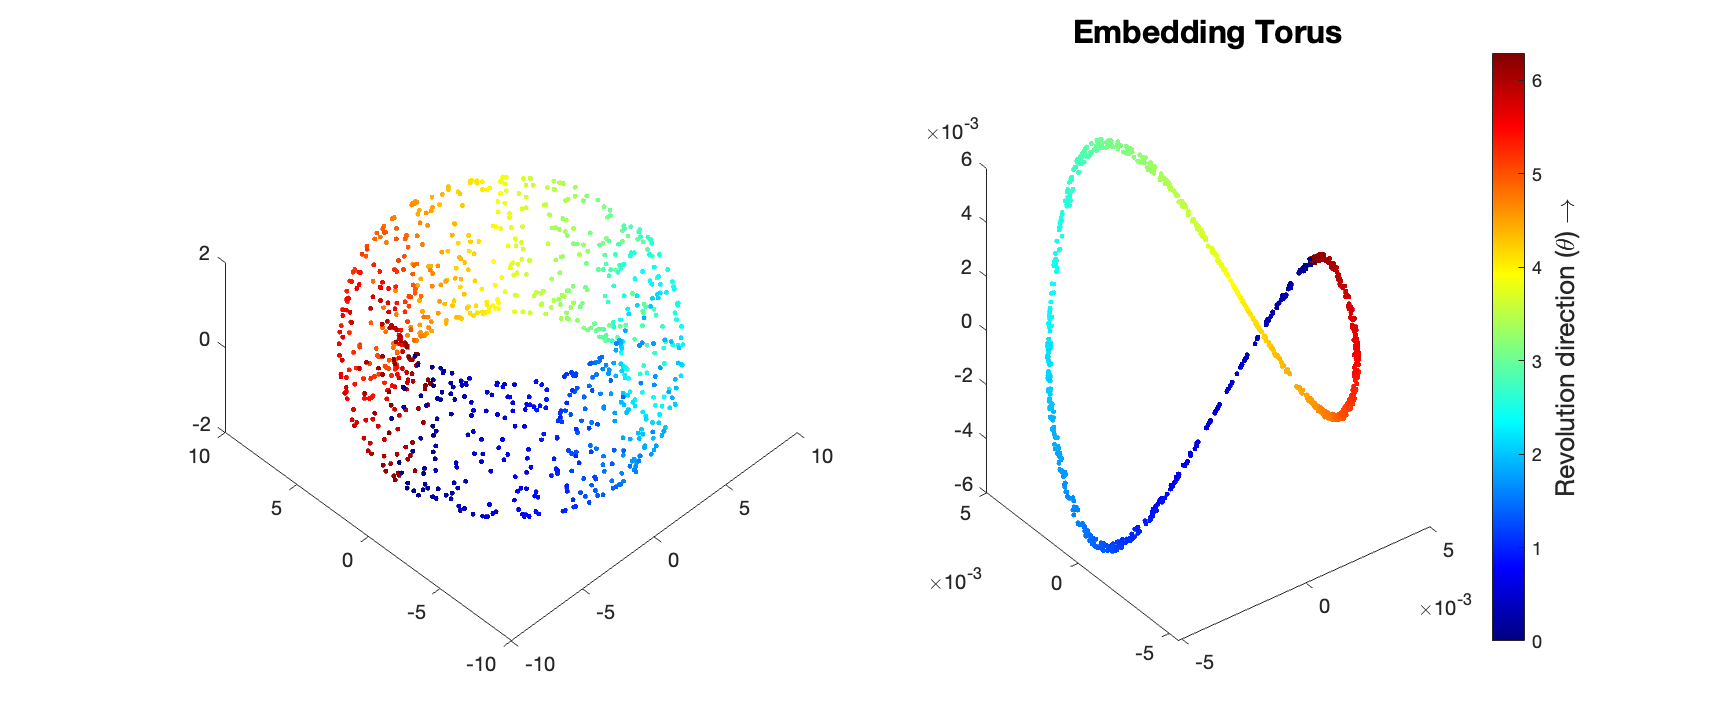

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])
numofpts = size(U, 1);
jetcustom = jet(numofpts); % partition the color bar from blue to red

subplot(1, 2, 1)
for i = 1:numofpts
    plot3(X(i, 1), X(i, 2), X(i, 3), '.', 'Color',  jetcustom(i, :))
    hold on
end
view([-45 60])

subplot(1, 2, 2)
for i = 1:numofpts
    plot3(U(i, 1), U(i, 2), U(i, 3), '.', 'Color',  jetcustom(i, :))
    hold on
end

colormap(jetcustom)
cb = colorbar;
caxis([0, 2*pi])
ylabel(cb,'Revolution direction (\theta) \rightarrow', 'Fontsize', 13)
title('Embedding Torus', 'Fontsize', 16, 'FontWeight', 'bold')

## Diffusion distance

In this section, we hope to find

- Why diffusion?

- Recover underlying manifold (diffusion distance)

n = 800;
diam = 0.8; % cyclinder radius
vert_v = 0.2; % vertical velocity
rotation_num = 3; % number of rotation
bandwidth = 0.5; % kernel bandwidth
diffu_time = 80;

theta = rand(n, 1)*rotation_num*2*pi;
X = zeros(n, 2); % initial
X(:, 1) = diam*cos(theta);
X(:, 2) = diam*sin(theta);
X(:, 3) = vert_v*theta;
% sort by revolution
[theta, idx] = sort(theta);
X = X(idx, :);

% apply diffusion map
[U, S] = DMapBasic(X, 100, 8, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 80.
(info) The first 10% number of points in bandwidth neighborhood is 63.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


### Comparison three distance

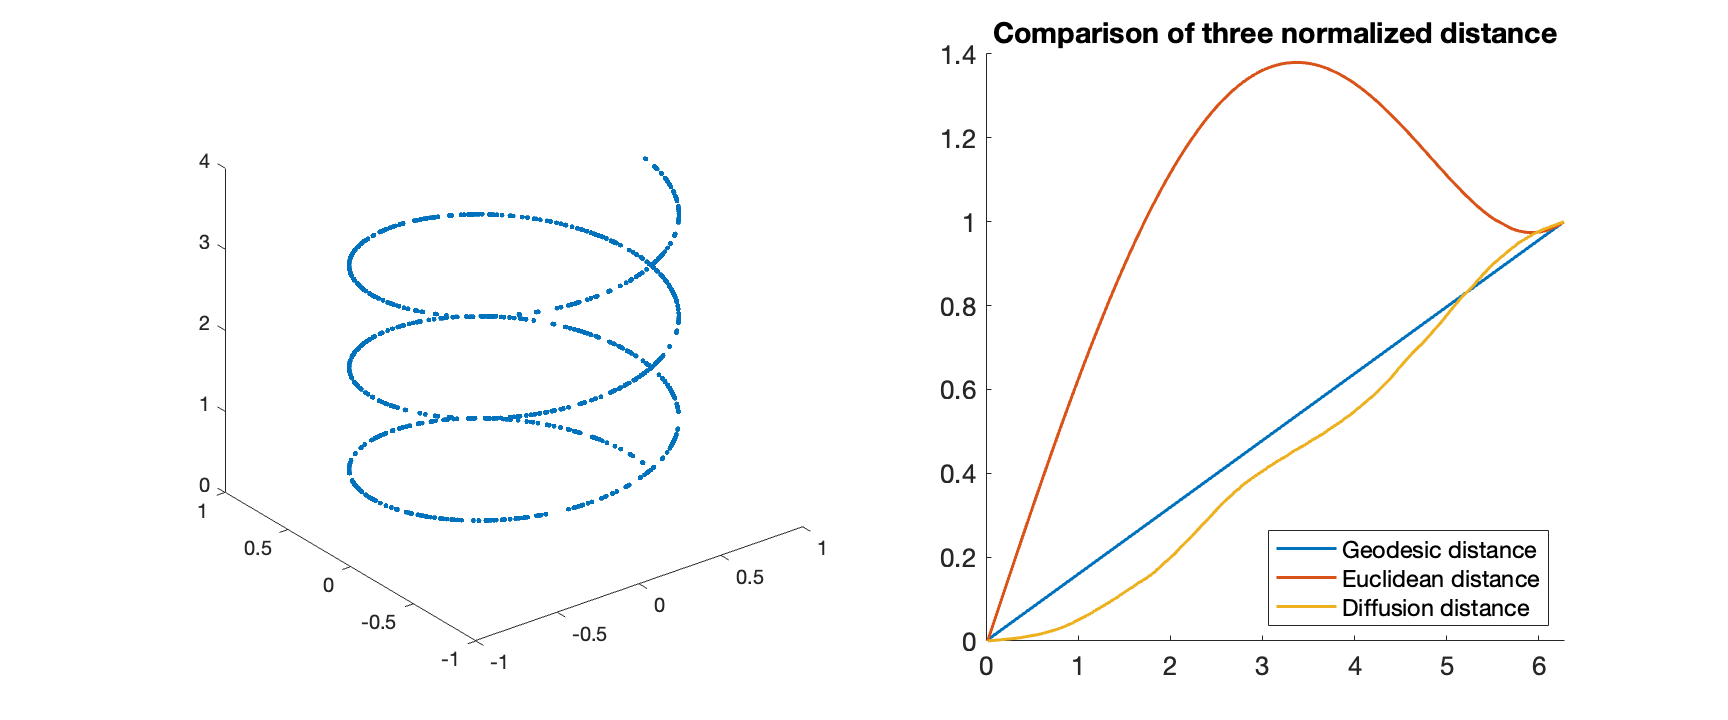

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])
subplot(1, 2, 1)
plot3(X(:, 1), X(:, 2),  X(:, 3), '.')

% geodsic distance
geod_dist = sqrt(diam^2+vert_v^2)*theta;
% ambient distance
tmpidx = 1:numel(theta);
idx = tmpidx(theta<2*pi);
amb_dist = vecnorm(X-X(1, :), 2, 2);
subplot(1, 2, 2)
hold on
plot(theta(idx), geod_dist(idx)/geod_dist(idx(end)), 'Linewidth', 1.5)
plot(theta(idx), amb_dist(idx)/amb_dist(idx(end)), 'Linewidth', 1.5)

diff_coord =  U*(diag(S).^50);
diffu_dist = vecnorm(diff_coord-diff_coord(1, :), 2, 2);
plot(theta(idx), diffu_dist(idx)/diffu_dist(idx(end)), 'Linewidth', 1.5)
legend('Geodesic distance', 'Euclidean distance', 'Diffusion distance', 'Location','southeast')
title('Comparison of three normalized distance')
set(gca, 'FontSize', 13) 
hold off

### Why diffusion

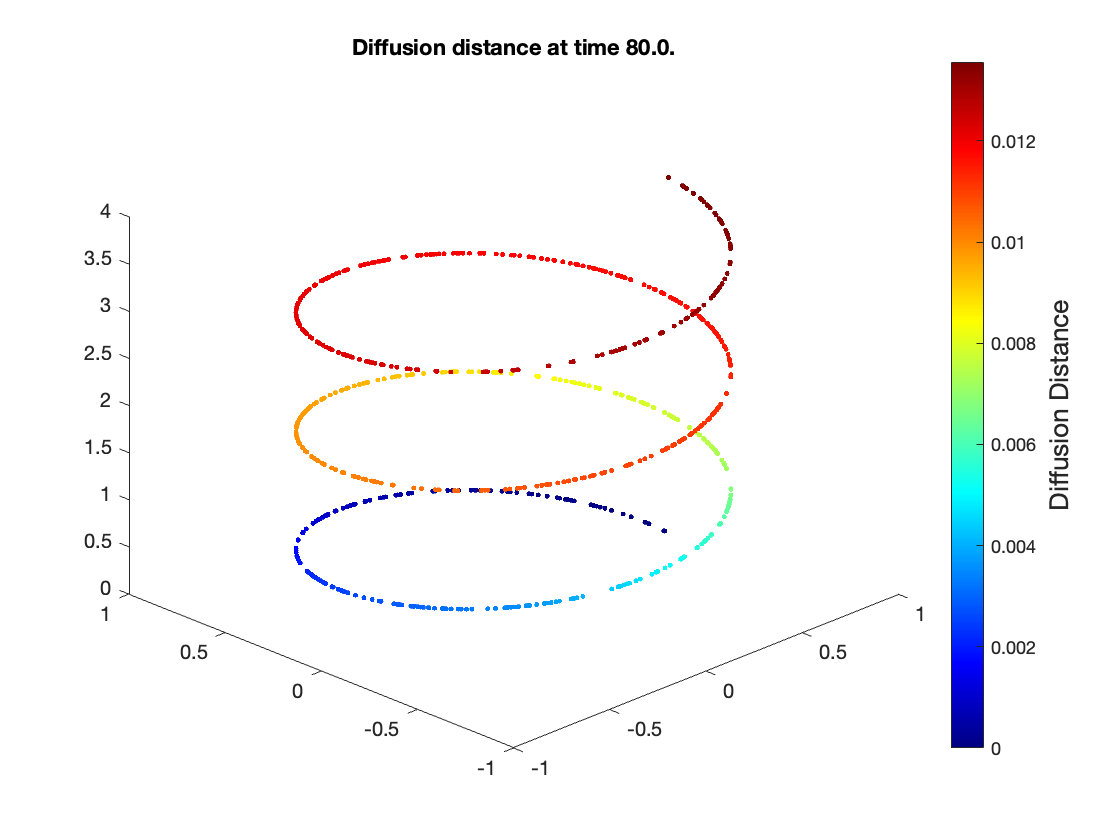

figure
numofpts = numel(diffu_dist);
jetcustom = jet(2*numofpts);
colormap(jet) 
cb = colorbar;
caxis([min(diffu_dist) max(diffu_dist)])
ylabel(cb,'Diffusion Distance', 'Fontsize', 13)

% compute diffusion along time
for t = 0:10:diffu_time
    % compute diffusion distance at time t
    diff_coord =  U*(diag(S).^t);
    diffu_dist = vecnorm(diff_coord-diff_coord(1, :), 2, 2);
    % search the specific distance
    labelbar = linspace(min(diffu_dist), max(diffu_dist), 2*numofpts); % label each nodes a number form min to max
    locateindex = knnsearch(labelbar', diffu_dist); % find our marker belong to which position in color bar
    hold on
    for i = 1:numofpts
        plot3(X(i, 1), X(i, 2), X(i, 3), '.', 'Color',  jetcustom(locateindex(i), :))
    end
    hold off

    title_str = sprintf('Diffusion distance at time %.1f.', t);
    title(title_str)
    view([-45 30])
    drawnow
end

## Dimension reduction for Mobius strip

n = 1000;
bandwidth = 0.6;
strip_width = 1.3;
color_map = false;

theta = rand(n, 1)*2*pi;
vert = rand(n, 1)*2-1;

X = zeros(n, 3); % initial
X(:, 1) = (1+0.5*vert.*cos(0.5*theta)).*cos(theta);
X(:, 2) = (1+0.5*vert.*cos(0.5*theta)).*sin(theta);
X(:, 3) = strip_width*vert.*sin(0.5*theta);
% sort by revolution or vertical
if color_map
    [theta, idx] = sort(theta);
    X = X(idx, :);
else
    [vert, idx] = sort(vert);
    X = X(idx, :);
end

% apply diffusion map
[U, S] = DMapBasic(X, 100, 4, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 100.
(info) The first 10% number of points in bandwidth neighborhood is 100.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


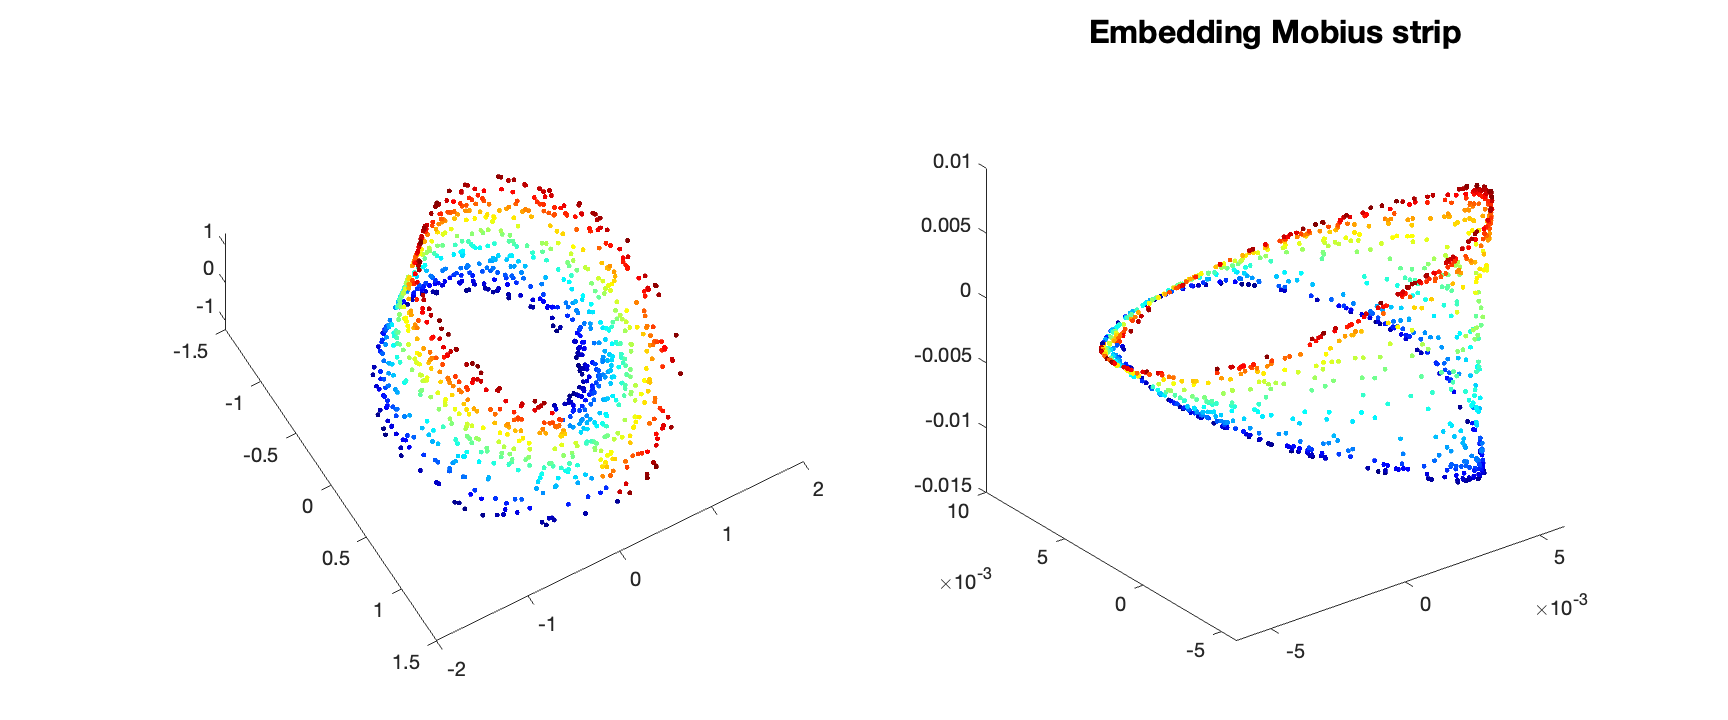

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])

subplot(1, 2, 1)
jetcustom = jet(n); % partition the color bar from blue to red
for i = 1:n
    plot3(X(i, 1), X(i, 2), X(i, 3), '.', 'Color',  jetcustom(i, :))
    hold on
end
view([60 75])

subplot(1, 2, 2)
for i = 1:n
    plot3(U(i, 1), U(i, 2), U(i, 3), '.', 'Color',  jetcustom(i, :))
    hold on
end

colormap(jetcustom)
caxis([0, 2*pi])
title('Embedding Mobius strip', 'Fontsize', 16, 'FontWeight', 'bold')

## Klein bottle (R^3)

load('Klein_bottle.mat')

n = size(X, 1);
[U, S] = DMapRoseland(X, 300, 4);

Step 1: Use k-means to find landmark.
(info) The number of landmark is chosen: 70.
Step 2: Construct bandwidth of kernel function.
(info) Now, there are 39.0096% distance being truncated.
(info) Now, the median number of reference points colse to one point is 43.
(info) Now, the first 10% number of points in bandwidth neighborhood is 23.
Step 3: Construct affinity matrix
Step 4: Compute the degree matrix. Note that W = Wref*Wref^T.
Step 5: Solve the eigenvectors by SVD.


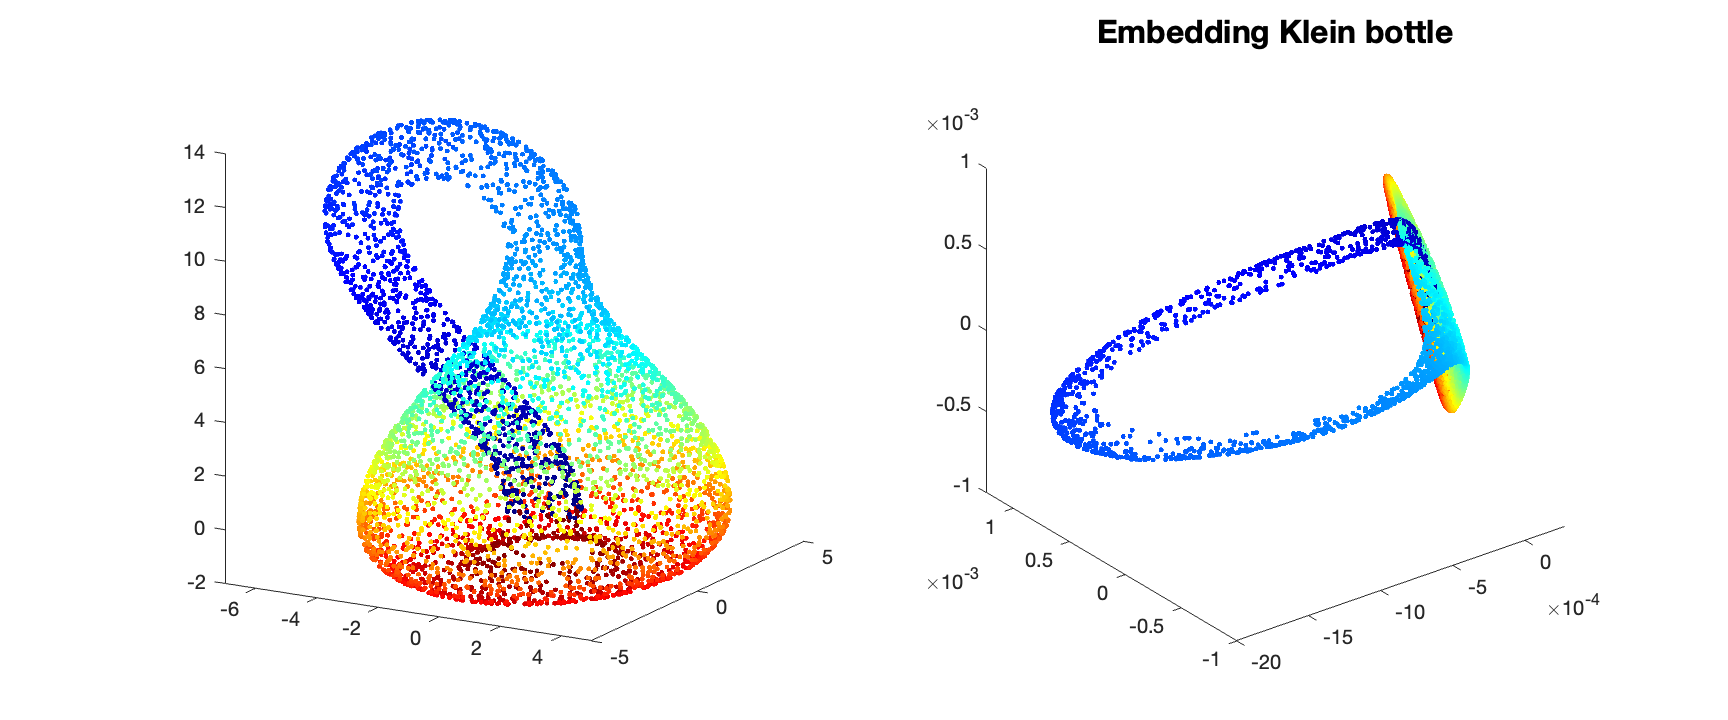


figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])

subplot(1, 2, 1)
jetcustom = jet(n); % partition the color bar from blue to red
for i = 1:n
    plot3(X(i, 1), X(i, 2), X(i, 3), '.', 'Color',  jetcustom(i, :))
    hold on
end
view([30 15])

subplot(1, 2, 2)
for i = 1:n
    plot3(U(i, 1), U(i, 2), U(i, 3), '.', 'Color',  jetcustom(i, :))
    hold on
end

colormap(jetcustom)
caxis([0, 2*pi])
title('Embedding Klein bottle', 'Fontsize', 16, 'FontWeight', 'bold')

## Klein bottle (R^4)

n = 1500;
bandwidth = 3;
color_map = true;

u = rand(n, 1)*2*pi;
v = rand(n, 1)*2*pi;

X = zeros(n, 4); % initial
X(:, 1) = (2*cos(v)+1).*cos(u);
X(:, 2) = (2*cos(v)+1).*sin(u);
X(:, 3) = 2*sin(v).*cos(0.5*u);
X(:, 4) = 2*sin(v).*sin(0.5*u);

if color_map
    [u, idx] = sort(u);
    X = X(idx, :);
else
    [v, idx] = sort(v);
    X = X(idx, :);
end

% apply diffusion map
[U, S] = DMapBasic(X, 100, 4, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 100.
(info) The first 10% number of points in bandwidth neighborhood is 100.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


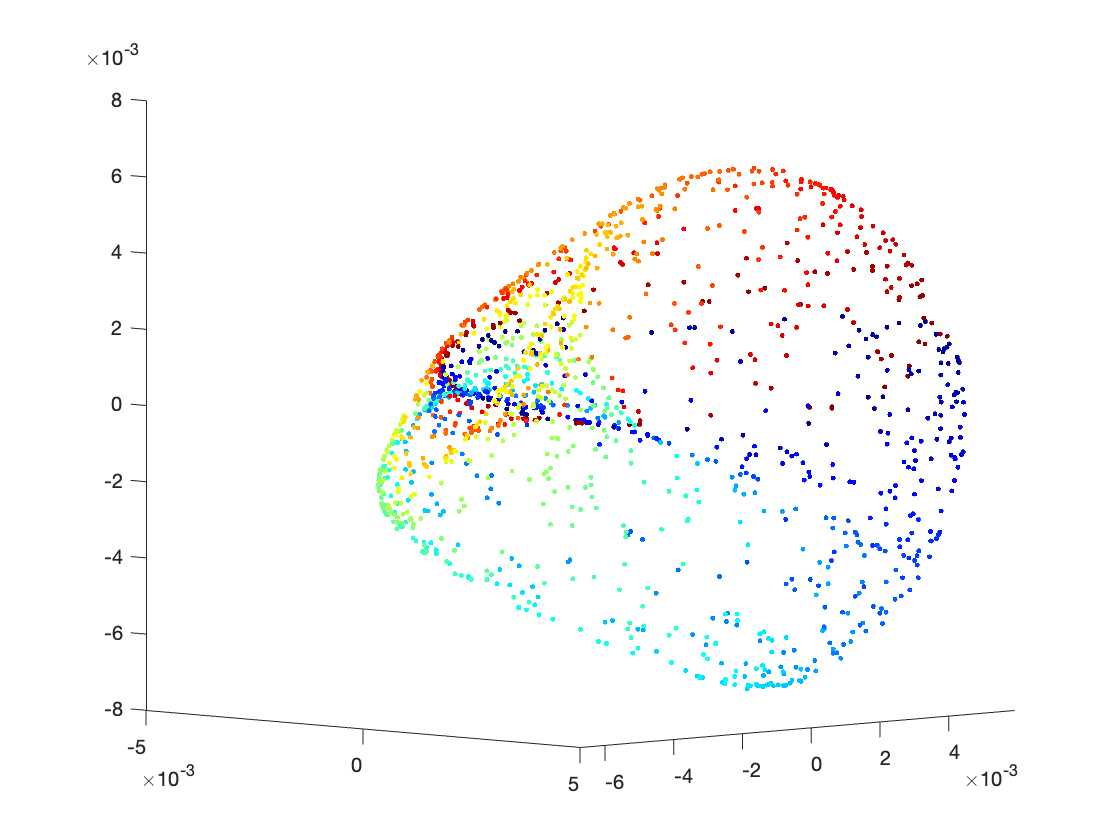

figure
jetcustom = jet(n); % partition the color bar from blue to red
for i = 1:n
    plot3(U(i, 1), U(i, 2), U(i, 3), '.', 'Color',  jetcustom(i, :))
    hold on
end
view([45 5])